# 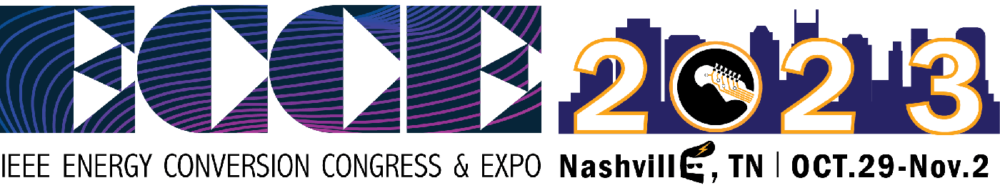

# Artificial Neural Network for Power Electronics 

### **Task 3: **The objective is to utilize an artificial neural network (autoencoder) to estimate the voltage sensor readings and predict potential sensor malfunctions.

# 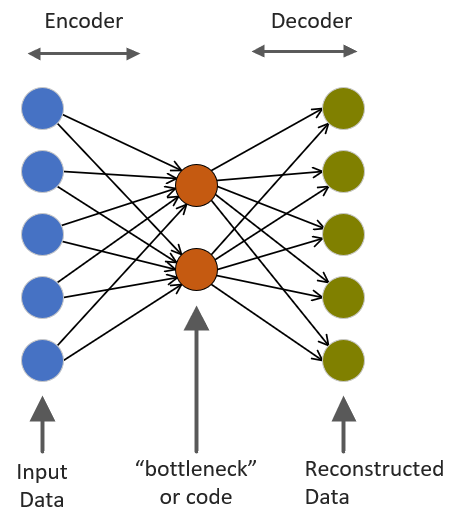

Figure 1: Generic autoencoder NN representation.

The so-called autoencoder is a type of neural network which consists of an enconder and decoder. The encoder maps the input to a hidden representation while the decoder attempts to map this hidden representation back to the original data input.

## **1º step: Create a function to generate data for training your ANN**

Autoencoders are an unsupervised learning technique and the "bottleneck" is a key attribute of the network design. By forcing a compressed knowledge representation of the original input data, if some sort of correlations exists in the data the autoencoder structure can learn this relationship.

Create a matrix called "V" with 5 lines (one for each of the sensors) and 1000 columns, representating the observations.

In our example, let's assume that all the sources varies at the instant and with the same shift. In addition limit the max voltage value to 50V and the min voltage value to 30V.

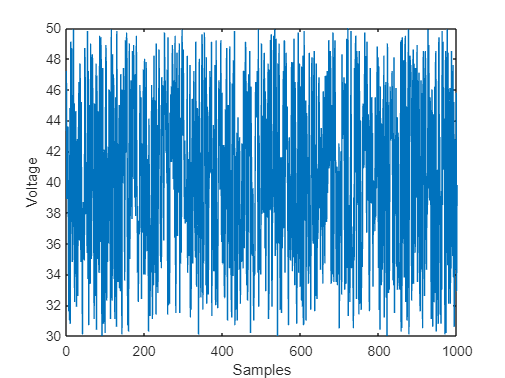

clear variables

Vmin = 30;   % min voltage value that the source can assume
Vmax = 50;   % max voltage value that the source can assume
no = 1000;   % number of observations

% Example ---------------------------------------
V1 = round(Vmin + (Vmax-Vmin) .* rand(no,1),1);

figure;
plot(V1)
xlim([0 no]), ylim([Vmin Vmax])
xlabel('Samples'), ylabel('Voltage')


V2 = V1;                % all the source varies equally
V3 = V1;
V4 = V1;
V5 = V1;

V = [V1 V2 V3 V4 V5]';  % 5x1000 data set
% ------------------------------------------------


## **2º step: Split data**

Before training let's separate part of the generated data for testing the performance of the NN after trained.

SplitRatio = 0.8;
% Create a random permutation of indices
ind = crossvalind('HoldOut', size(V, 2), SplitRatio);
 
% Use the indices to split the data into training and testing sets
V_train = V(:,ind == 0);
V_test = V(:,ind == 1);

## **3º step: **Neural Network configuration

The following code opens the Matlab Neural Network Fitting app interface.

% Autoencoder NN
% *use rng(0,'twister') for reproducibility

hiddenSize = 2;     % Number of neurons in the code layer

% Autoencoder parameters
autoNN = trainAutoencoder(V_train,hiddenSize,...
        'EncoderTransferFunction','satlin',...       % activation function for encoder layer
        'DecoderTransferFunction','purelin',...      % activation function for decoder layer
        'L2WeightRegularization',0.01,...
        'SparsityRegularization',2,...
        'SparsityProportion',0.20);


*Autoencoder parameters:*

- `Encoder and Decoder TransferFunction: activation fcn, such as logsig, satlim, purelim `

- `Maximum number of iterations(epochs): Ex: 'MaxEpochs',300`

- `L2WeightRegularization and SparsityRegularization are parameters of the cost function used for training`

- `SparsotyProportion is a parameter of the SparcityRegularization and indicates the desired proportion of the training examples a neuron reacts to.`

- `Training algorithm: Ex:'trainscg' (default)`

## **4º step: Analyze the performance **

Use the test dataset to analyze the neural network performance by comparing its output and comparing with the target values.

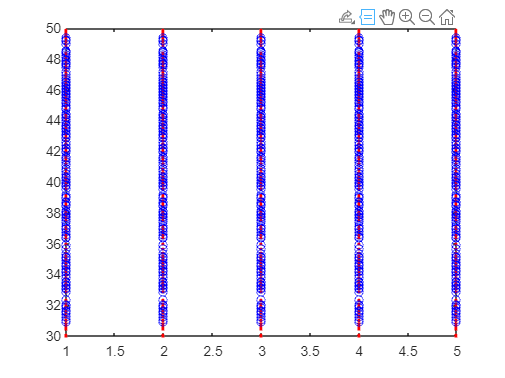

V_Reconstructed = predict(autoNN,V_test);
figure;
plot(V_test,'r.');
hold on
plot(V_Reconstructed,'bo');
hold off

MSE = mse(V_test-V_Reconstructed)   % mean of squared errors

MSE = 0.0328

## **5º step**: Deploy the Neural Network to Simulink 

Create the neural network "block" in the Simulink environment.

net = network(autoNN)   % convert the autoencoder object into network object 
gensim(net)             % export to Simulink

## **6º step**: Open the main model

Open the complete model for demo 3. When the model opens, copy and paste the neural network into the main model using the marked area. The inputs of the neural network are the voltage measurements.

open('ECCE_demo3_model')
Vdc = 38;


## **7º step**: Simulate the model

Now, click on the *Run* button to let your NN estimate the voltage readings. You can check on the *Display* te compararion between the NN output and the actual value read from the sensors. 

## **8º step**: Check the Results: apply a drift to sensor 1

Simulate a drift in the measurements of sensor 1 (use the switch to define the drift).

Again, compare the NN output with the sensor measurement.

## **Instructor Team:**

Joao O. P. Pinto – Chair Oak Ridge National Laboratory – Knoxville 

Burak Ozpineci – Co-Chair Oak Ridge National Laboratory – Knoxville 

Marcio L. M. Kimpara – Co-Chair Oak Ridge National Laboratory – Knoxville

Pedro Eugênio M. Ribeiro - Oak Ridge National Laboratory – Knoxville 

Renata Rezende Reis - Federal University of Mato Grosso do Sul (UFMS) - Brazil

Feel free to contact us at [pintoj@ornl.gov](mailto:pintoj@ornl.gov) 